# Operações relacionadas à leitura e escrita de um arquivo (binário, textual).

Essas operações de leitura e escrita de arquivos - sejam eles binários ou textuais - podem ser feitas de diversas formas, usando funções primitivas ou de alto nível.

Para melhor compreensão das conversões entre números e caracteres, apresenta-se tabela ASCII

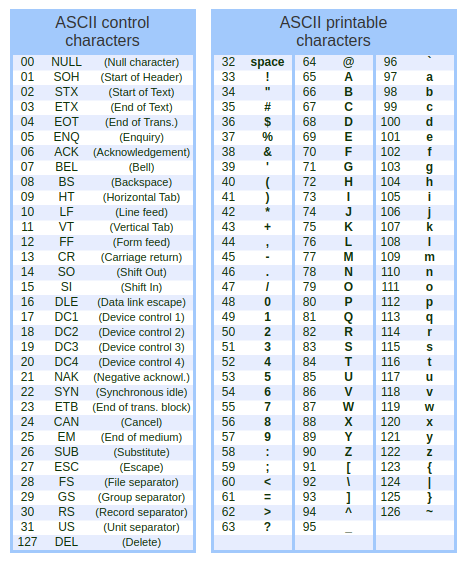

## A criação de um arquivo textual.

Uso das funções primitivas fopen, fwrite, fread, fclose.

Filename    = fullfile(pwd, 'Temp', 'NewTextFile.txt');
TextToWrite = sprintf('One\nTwo\nThree');

fileID = fopen(Filename, 'wt');

fwrite(fileID, TextToWrite, 'char');
fclose(fileID);

## A leitura desse arquivo textual.

Essa leitura pode ser feita de várias formas:

- Usando as funções primitivas (fopen, fread e fclose), calculando a transposta e convertendo para *string.*

fileID = fopen(Filename, 'r');
array1  = char(fread(fileID)')
fclose(fileID);

- Usando as funções primitivas (fopen, fread e fclose), lendo como "vetor linha" e *string*.

fileID = fopen(Filename, 'r');
% array2 = fread(fileID, [1, Inf], 'uint8=>char')
array2 = fread(fileID, [1, Inf], '*char')
fclose(fileID);

- Usando a função fscanf.

fileID = fopen(Filename, 'r');
array3 = fscanf(fileID, '%c')
fclose(fileID);

- Usando funções de alto nível fileread e readcell.

array4 = fileread(Filename)
array5 = strjoin(readcell(Filename, 'Delimiter', '\n'), '\n')

## Funções primitivas auxiliares

No caso do uso de funções primitivas na leitura de arquivos, cabe o uso das seguintes funções auxiliares:

- fseek

- ftell

- frewind

- feof